# **Simple Neural Network using DL-Array (v0.6)**

Written by *Sunny Guha *

In this short script, I have built an MNIST classifier using low-level dlarray functionality. The utility of this exercise is to get a grip on low level deep learning functions in MATLAB. This also demonstrates simple ***dl-array*** workflows for deep learning. 

MNIST dataset contains handwritted digits of size 28*28*1. The task is to predict the labels (0-9). The dataset can be downloaded from: [http://yann.lecun.com/exdb/mnist/](http://yann.lecun.com/exdb/mnist/)

Download and extract the dataset in the current working folder of this live-script.

**Note** - This is meant to be the *quickest implementation* *to write* and not the most performant. 

**Layout of this Live-Script**

Section 1: Loading and Pre-processing the data

Section 2: Creating Network Parameters

Section 3: Training the Model

Section 4: Testing the Model

Section 5: Utility function that perform that actual computations.

## 1) Loading & Pre-processing Data

We beign by defining some parameters

learning_rate = 0.01;
num_epochs = 10;
batch_size = 32;

Let us begin by loading in the train and test set and performing pre-processing on it. The preprocessing step is to normalize the image in the range of 0-1. Preporcessing is performed in the *load_img* script. The load_img script borrows heavily from the `processImagesMNIST` script of [Train Variational Autoencoder (VAE) to Generate Images](https://www.mathworks.com/help/deeplearning/ug/train-a-variational-autoencoder-vae-to-generate-images.html) example. 

We will not worry about validation set in this simple example. 

filenameImagesTrain = 'mnist\train-images.idx3-ubyte';
filenameLabelsTrain = 'mnist\train-labels.idx1-ubyte';
filenameImagesTest = 'mnist\t10k-images.idx3-ubyte';
filenameLabelsTest = 'mnist\t10k-labels.idx1-ubyte';
XTrain = load_img(filenameImagesTrain);

reading MNIST.....
done loading


YTrain = load_label(filenameLabelsTrain);

Reading MNIST Labels.......
done loading


XTest = load_img(filenameImagesTest);

reading MNIST.....
done loading


YTest = load_label(filenameLabelsTest).';

Reading MNIST Labels.......
done loading


Our network contains 10 ouput neurons corresponding to the recognized digit. For this purpose we need to convert the labels to one-hot representation.

% One Hot Encoding of Train-labels
[wid,len]=size(XTrain);
y =zeros([10,len]);
for i = 1:len
    y(YTrain(i)+1,i) = 1;
end

## 2) Creating the Network

We build a three layered network.

Input (764 - (flattened images))  -> 100 neurons -> relu -> 100 neurons -> relu -> 10 neurons (output). It is important to initialize the network weights within the range of -1 to 1 otherwise the layer outputs would be skwewd. The parameters need to be converted to dl-arrays for the auto-diff computation to be tracked. The actual network computations are performed in the functions defined in the last section.

Let us now define the parameters for our network.

% Defining weight and bias matrices 
W1 = rand([784,100])*2-1; 
W2 = rand([100,100])*2-1;
W3 = rand([100,10])*2-1;
B1 = rand([100, 1])*2-1;
B2 = rand([100, 1])*2-1;
B3 = rand([10, 1])*2-1;
% We convert these regulars arrays to dlarrays
W1 = dlarray(W1);
W2 = dlarray(W2);
W3 = dlarray(W3);
B1 = dlarray(B1);
B2 = dlarray(B2);
B3 = dlarray(B3);
% Bundle all the parameters in a cell-array
parameters= {W1,W2,W3,B1,B2,B3};

## 3) Training our Network

We perform training over a certain number of epochs. *perform_training*  function takes in input, label, parameters, learning rate and batch_size as input. Average per-batch loss is reported at the end of each epoch.

The output of this training step are trained parameters.

% Training our network
for i=1:num_epochs
    parameters = perform_training(XTrain,y,parameters,learning_rate,batch_size);
end

per-batch loss for this epoch : 2.7983
per-batch loss for this epoch : 0.76834
per-batch loss for this epoch : 0.50635
per-batch loss for this epoch : 0.41715
per-batch loss for this epoch : 0.36938
per-batch loss for this epoch : 0.33749
per-batch loss for this epoch : 0.31381
per-batch loss for this epoch : 0.29501
per-batch loss for this epoch : 0.2794
per-batch loss for this epoch : 0.26622


## **4) Testing the Network**

Compute performance of our network on the test set

correct=permform_test(XTest,parameters,batch_size,YTest);
accuracy=correct/length(YTest)*100;
disp(['The accuracy on the test set is: ',num2str(accuracy)])

The accuracy on the test set is: 91.02


Now lets see the output of a single sample.

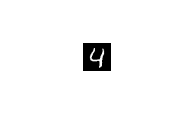

idx = 5;
temp = XTest(:,idx);
% Display the image
imshow(reshape(temp,[28,28]))

disp(['Lable is ',int2str(YTest(idx))]);

Lable is 4


out = extractdata(predict(temp, parameters));
disp(['Prediction is ', int2str(out)]);

Prediction is 4


## 5) Utility functions

Here we define the functions that perform the bulk of training and testing.

1) **train(input,lables,parameters)** performs one batch of training and calculates the loss and gradients. Output is the gradient wrt to parameters.

2) **perform_training(input,output,parameters,lr,batch_size)** performes the training on the entire dataset. It calls train function multiple times to do the training and also updates parameters after each call.

3) **predict(input,parameters)** computes the output of model given input and parameters.

4) **permform_test(input,parameters,batch_size,target)** computes the performance of our model on the entire test set. Predict function is called multiple times.

#### DL-Array usage

1) After performing computations gradients can be computed using **dlgradient** function which takes variable and parameters as arguments.

2) To enable computation of gradients the function needs to be evaluated through **dlfeval** which keeps track of gradient flow. This is done in *perform_training* function.

3) Updation of parameters is done manually. One can use adam or some other optimizer to perform this step directly.

function [grads,losstot]=train(input,output,parameters)
    W1 = parameters{1};
    W2 = parameters{2};
    W3 = parameters{3};
    b1 = parameters{4};
    b2 = parameters{5};
    b3 = parameters{6};
    %Perform the layerwise computation
    H1 = W1.' * input + b1;
    A1 = relu(H1);
    H2 = W2.' * A1 + b2;
    A2 = relu(H2);
    H3 = W3.' * A2 + b3;
    A3 = softmax(H3,'DataFormat','CB');
    % Cross Entropy loss is used
    loss = crossentropy(A3,output,'DataFormat','CB');
    losstot = sum(loss);
    % Gradients of loss wrt parameters
    grads = dlgradient(losstot,parameters);

end

function finalparam=perform_training(input,output,parameters,lr,batch_size)
    [~,len]=size(input);
    mult=floor(len/batch_size);
    tot_loss=0;
    % loop over mini-batches
    for i=0:(mult-1)
        test = input(:,batch_size*i+1:batch_size*(i+1));
        sol = output(:,batch_size*i+1:batch_size*(i+1));
        [grad,loss] = dlfeval(@train,test,sol,parameters);
        for j=1:6
            parameters{j}=parameters{j}-lr*grad{j};
        end
        tot_loss = tot_loss + extractdata(loss);
    end
    % remaining samples
    test = input(:,batch_size*mult+1:end);
    sol = output(:,batch_size*mult+1:end);
    [grad,~] = dlfeval(@train,test,sol,parameters);
    for i=1:6
        parameters{i}=parameters{i}-lr*grad{i};
    end
    finalparam=parameters;
    disp(['per-batch loss for this epoch : ',num2str(tot_loss/mult)]);
end

function out=predict(input,parameters)
    W1 = parameters{1};
    W2 = parameters{2};
    W3 = parameters{3};
    b1 = parameters{4};
    b2 = parameters{5};
    b3 = parameters{6};
    H1 = W1.' * input + b1;
    A1 = relu(H1);
    H2 = W2.' * A1 + b2;
    A2 = relu(H2);
    H3 = W3.' * A2 + b3;
    A3 = softmax(H3,'DataFormat','CB');
    % Argmax determines the label
    [~,idx] = max(A3);
    % Offset by 1 
    out = idx-1;
end

function res=permform_test(input,parameters,batch_size,target)
    [wid,len]=size(input);
    mult=floor(len/batch_size);
    res = 0;
    for i=0:(mult-1)
        inp = input(:,batch_size*i+1:batch_size*(i+1));
        targ = target(batch_size*i+1:batch_size*(i+1));
        idx = predict(inp,parameters);
        corr = (idx==targ);
        res= res + sum(corr);
    end
    inp = input(:,batch_size*mult+1:end);
    targ = target(batch_size*mult+1:end);
    idx = predict(inp,parameters);
    corr = (idx==targ);
    res= res + sum(corr);
    end
